# Problem 1

clear
a = 100;
s = tf('s');
G = 1/(s^2+a/50*s+a^2)*[s-a^2 a*(s+1) ; -a*(s+1) s-a^2];

Part a

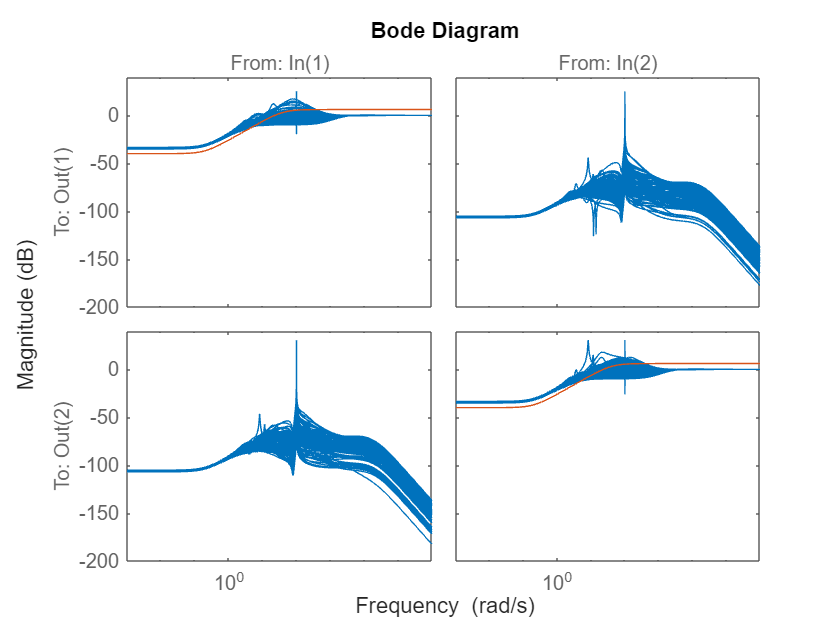

Wp = (0.5*s+20)/(s+0.2)*eye(2);
Wi = (20*s+10)/(s+100);
delta1 = ultidyn('delta1', [1 1]);
delta2 = ultidyn('delta2', [1 1]);
Gu = [1+delta1*Wi 0 ; 0 1+delta2*Wi] * G;
[K, CL, GAM] = mixsyn(Gu, Wp, [], Wi);
S = inv(eye(2) + Gu*K);
Svec = usample(S, 100);
bodemag(Svec, 1/Wp)

[mu, flag] = robmu(S)

mu = 1.8492

flag = 0

[mu, flag] = perfmu(S)

mu = 2.7662

flag = 1

The system is not robustly stable.

Part b

P = [Wp Wp*Gu ; zeros([2 2]) Gu ; eye(2) Gu];
[K, CLPerf, info] = musyn(P, 2, 2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           122.6        57.19        57.64             2
    2           14.25        10.16        10.26            28
    3           5.427        5.335        5.341            44
    4           4.263        4.256        4.267            74
    5           3.886        3.877        3.934            82
    6            3.66        3.671        3.874            82
    7           3.679        3.682         3.78            76
    8           3.668        3.696        3.701            78

Best achieved robust performance: 3.67



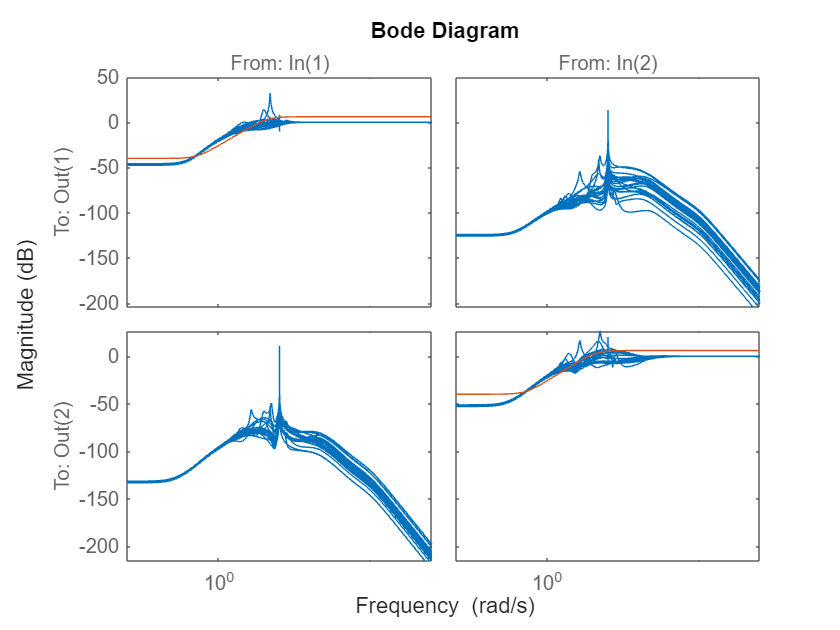

S = inv(eye(2) + Gu*K);
bodemag(S, 1/Wp)

N = lft(P, K);
[mu, flag] = robmu(N)

mu = 2.8004

flag = 0

[mu, flag] = perfmu(N)

mu = 3.6063

flag = 1

RS and RP are not acheived.

# Problem 2

Part b

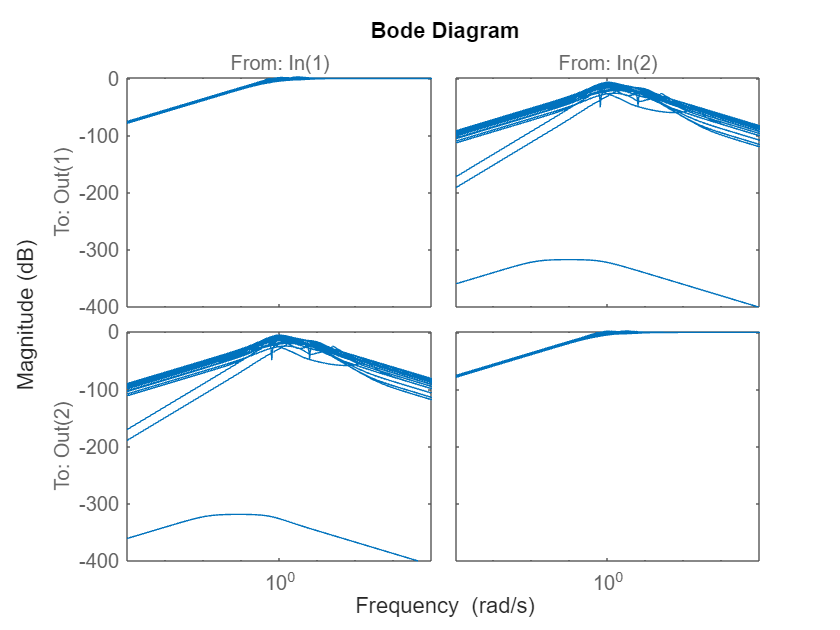

clear
s = tf('s');
G = 1/(75*s+1) * [-87.8 1.4 ; -108.2 -1.4];
K = 0.7/s * inv(G);
Wi = (s+0.2)/(0.5*s+1);
Wp = (s/2+0.05)/s;
diagu = [ultidyn('delta1', [1 1]) 0 ; 0 ultidyn('delta2', [1 1])];
fullu = ultidyn('delta3', [2 2]);
Gu_diag = G*(eye(2)+Wi*diagu);
Gu_full = G*(eye(2)+Wi*fullu);
S_diag = inv(eye(2)+Gu_diag*K);
bodemag(S_diag)

[mu, flag] = perfmu(S_diag)

mu = 1.4218

flag = 1

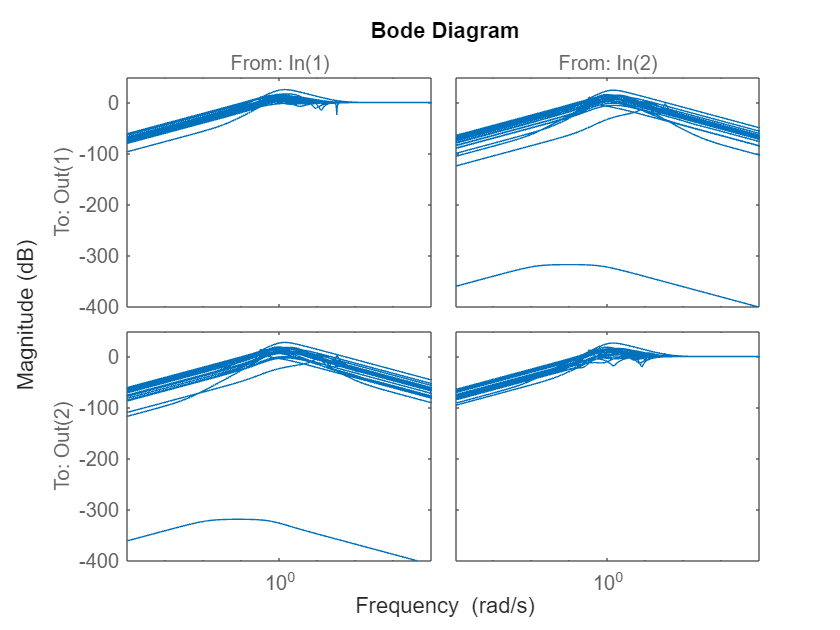

S_full = inv(eye(2)+Gu_full*K);
bodemag(S_full)

[mu, flag] = perfmu(S_full)

mu = 5.8219

flag = 1

# Problem 3

Part a

clear
s = tf('s');
sys = [1/(s+5) (s-2)/(s+10) ; 10/(s^2+4*s+15) 3*s/(4*s+3)];
calc_inf_norm(sys, 0.0001) % my function

ans = 1.2500

norm(sys, 'inf') % MATLAB built in

ans = 1.2500

Part b

sys = [1/(s+5) 1/(s+10) ; 10/(s^2+4*s+15) 3/(4*s+3)];
calc_2_norm(sys) % my function

ans = 1.1655

norm(sys) % MATLAB built in

ans = 1.1655